clear
sensor_pin = 'A5';
pan_pin = 'D9';
tilt_pin = 'D10';

% a = arduino();
a = arduino('COM10', 'Uno', 'Libraries', 'Servo');

pan_servo = servo(a,pan_pin,"MinPulseDuration",700*10^-6,'MaxPulseDuration',2300*10^-6);
tilt_servo = servo(a,tilt_pin,"MinPulseDuration",700*10^-6,'MaxPulseDuration',2300*10^-6);

%move servo to middle position for next scan

writePosition(pan_servo,Deg2Pos(0));
writePosition(tilt_servo,Deg2Pos(0));

% initilize pan and tilt servo to upper left corner of scan image
count = 1;
points = [];
for tilt_angle = -30:2:30
    disp(tilt_angle);
    writePosition(tilt_servo,Deg2Pos(tilt_angle));
    pause(0.1);
    for pan_angle = -30:2:30
        disp(pan_angle);
        writePosition(pan_servo,Deg2Pos(pan_angle));
        %take a scan here for each step
        points= [points,get_coordinates(a,pan_angle,tilt_angle)];
        count = count + 1;
        pause(0.1);
    end

end

   -30



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



   -28



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



   -26



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



   -24



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



   -22



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



   -20



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



   -18



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



   -16



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



   -14



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



   -12



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



   -10



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    -8



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    -6



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    -4



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    -2



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



     0



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



     2



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



     4



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



     6



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



     8



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    10



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    12



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    14



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    16



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    18



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    20



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    22



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    24



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    26



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    28



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    30



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



% initilize pan and tilt servo to upper left corner of scan image
count = 1;
points = [];
tilt_angle = -5;
writePosition(tilt_servo,Deg2Pos(tilt_angle));
for pan_angle = -30:2:30
    disp(pan_angle);
    writePosition(pan_servo,Deg2Pos(pan_angle));
    %take a scan here for each step
    points= [points,get_coordinates(a,pan_angle,tilt_angle)];
    count = count + 1;
    pause(0.1);
end

   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



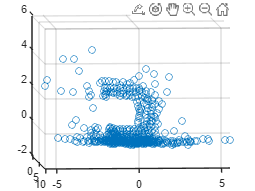

%% DO NOT TOUCH

clf
x = points(1,:);
x = x(z<10);
y = points(2,:);
y = y(z<10);
z = points(3,:);
z = z(z<10);
scatter3(x,z,y)

p = [-30:2:30]

p =    -30   -28   -26   -24   -22   -20   -18   -16   -14   -12   -10    -8    -6    -4    -2     0     2     4     6     8    10    12    14    16    18    20    22    24    26    28    30


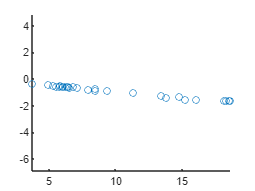

scatter(x,y)
axis equal

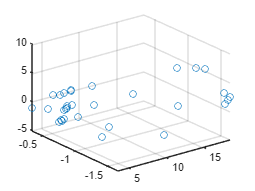

clf
x = points(1,:);
%x = x(z<10);
y = points(2,:);
%y = y(z<10);
z = points(3,:);
%z = z(z<10);
scatter3(x,y,z)

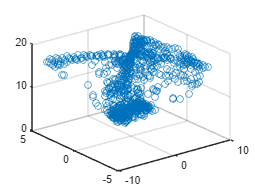

%% TOUCH
clf
z = points(3,:);
%z = z(z<15);
x = points(1,:);
%x = x(z<15);
y = points(2,:);
%y = y(z<15);
scatter3(x,z,y)

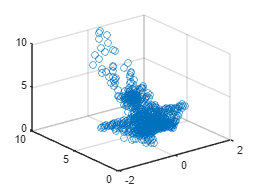

clf
x = points(1,:);
x = x(z<10);
y = points(2,:);
y = y(z<10);
z = points(3,:);
z = z(z<10);
scatter3(x,z,y)

disp(points);